clc
clear
close all

## Specification of Parameters

Jm = 1; % Moment of inertia of motor [kgm^2]
Jl = 1; % Moment of inertia of link [kgm^2]
Ks = 1; % Stiffness of shaft [Nm/rad]
Bm = 1; % Viscous damping of motor [Nm/(rad/s)]

## Specification of System Matrices

A = [0 0 1 0; 0 0 0 1; -Ks/Jm Ks/Jm -Bm/Jm 0 ; Ks/Jl -Ks/Jl 0 0]; % !!Insert your system matrix
B = [0 ; 0 ; 1/Jm ; 0]; % !!Insert your input matrix
C = [0 0 0 1]; % !!Insert your output matrix
D = 0; % !!Insert your direct feedthrough matrix

## Define Model Object

Write "help ss" to see how to define a model object

sys = ss(A,B,C,D); % !!Define model object

## Simulate System using lsim

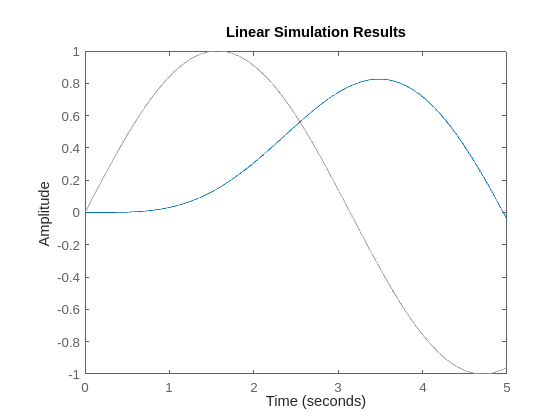

t = 0:0.01:5; % Time vector for simulation [s]
u1 = sin(t);  % Input for simulation (tau_m(t)=1) [Nm]
u2 = ones(size(t)); % Input for simulation (tau_m(t)=sin(t)) [Nm]
% Write "help lsim" to see how to use the function
lsim(sys, u1, t)

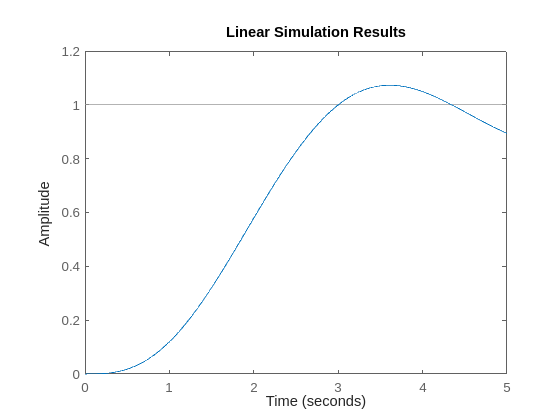

lsim(sys,u2,t)

## Simulate system using ode45

t = 0:0.01:5; % Time vector for simulation [s]
u1 = sin(t);  % Input for simulation (tau_m(t)=1) [Nm]
u2 = ones(size(t)); % Input for simulation (tau_m(t)=sin(t)) [Nm]
% Write "help ode45" to see how to use the function
ode45(sys , [0 5], 0)

Error using exist
The first input to exist must be a string scalar or character vector.

Error in packageAsFuncHandle (line 6)
    odeTreatAsMFile = exist(ode) == 2; %#ok<EXIST>

Error in ode45 (line 86)
[ode, odeIsFuncHandle, odeTreatAsMFile] = packageAsFuncHandle(ode);

## Make Step Response of System

Write "help step" to see how to use the function and use the model object sys

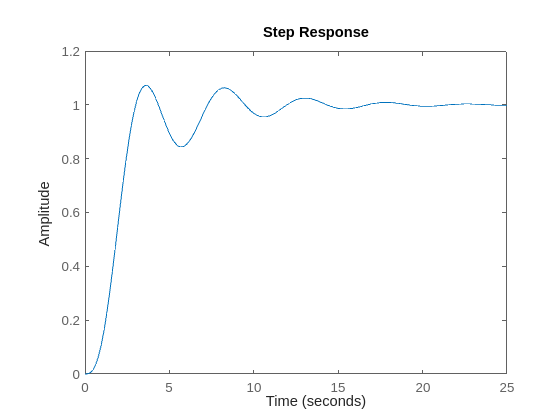

step(sys)

## Discretize the System

T = 0.01; % !!Specify an appropriate sample time
% Write "help c2d" to see how to use the function and use the model object sys
sysd = c2d(sys,T); % !!Define discrete time model object

## Simulate System using lsim

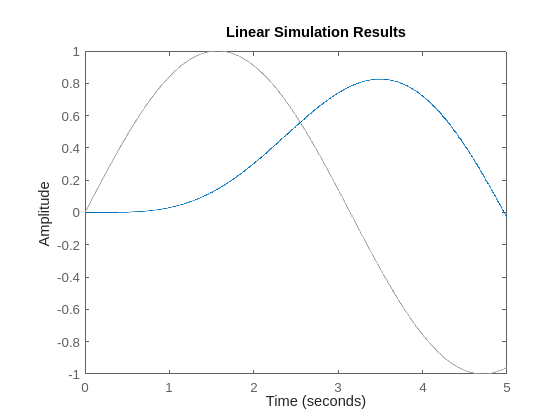

t = 0:T:5; % Time vector for simulation [s]
u1 = sin(t);  % Input for simulation (tau_m(t)=1) [Nm]
u2 = ones(size(t)); % Input for simulation (tau_m(t)=sin(t)) [Nm]
% Write "help lsim" to see how to use the 
lsim(sysd,u1,t)

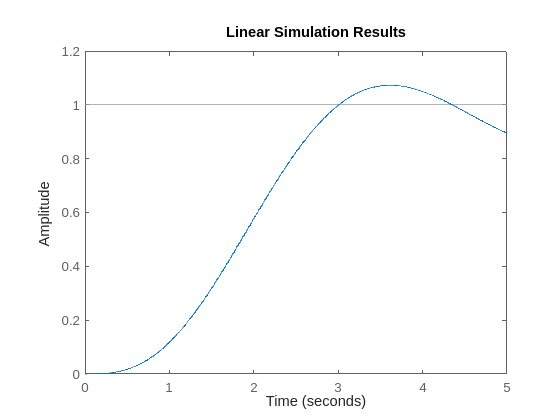

lsim(sysd,u2,t)

## Draw Bode Plot of the System

Write "help bode" to see how to use the function and use the model objects sys and sysd

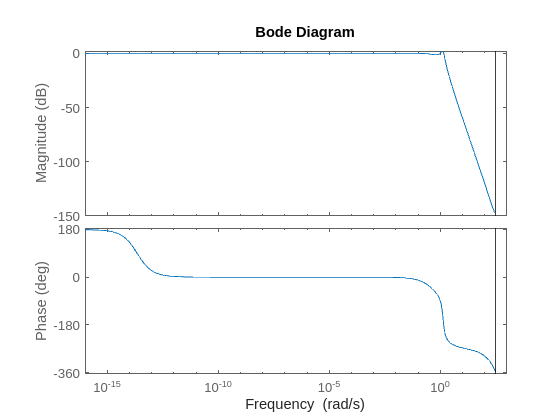

bode(sysd)

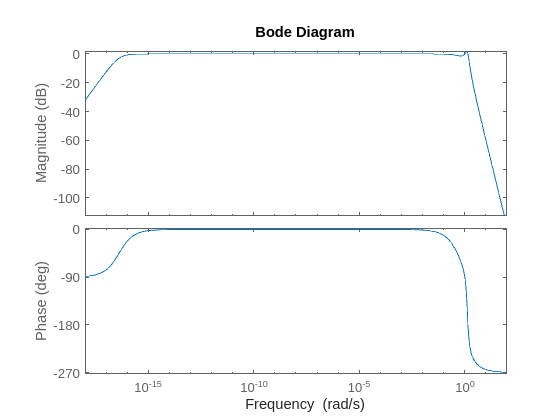

bode(sys)

[b,a]=ss2tf(A,B,C,0)

b =      0     0     0     1     0


a =     1.0000    1.0000    2.0000    1.0000   -0.0000


tfsys = tf(b,a)

tfsys =
 
                  s
  ---------------------------------
  s^4 + s^3 + 2 s^2 + s - 4.091e-17
 
Continuous-time transfer function.
Model Properties


step(tfsys)

tfsysd = c2d(tfsys,0.01)

tfsysd =
 
  1.662e-07 z^3 + 4.971e-07 z^2 - 4.979e-07 z - 1.654e-07
  -------------------------------------------------------
         z^4 - 3.99 z^3 + 5.97 z^2 - 3.97 z + 0.99
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


t = 0:0.01:5; % Time vector for simulation [s]
u1 = sin(t);  % Input for simulation (tau_m(t)=1) [Nm]
u2 = ones(size(t)); % Input for simulation (tau_m(t)=sin(t)) [Nm]
% Write "help lsim" to see how to use the function
lsim(tfsysd, u1, t)